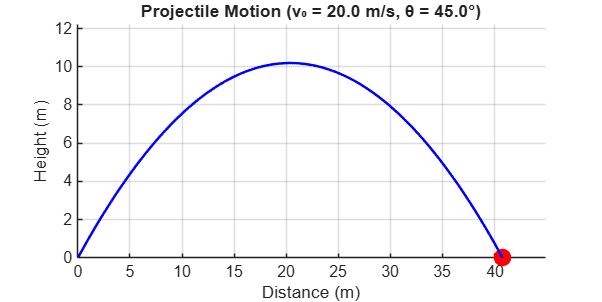

clc; clear; close all;

v0 = 20;       
theta = 45;    
g = 9.81;      
dt = 0.02;     
t = linspace(0, 2*v0*sind(theta)/g, 200);
x = v0*cosd(theta).*t;
y = v0*sind(theta).*t - 0.5*g*t.^2;

% Create a figure for the projectile motion plot
f = figure('Position',[300 200 800 400]);
hold on; grid on;
% Label the axes and set the title with initial velocity and angle
xlabel('Distance (m)');
ylabel('Height (m)');
title(sprintf('Projectile Motion (v₀ = %.1f m/s, θ = %.1f°)', v0, theta));
% Set the axis limits based on the maximum x and y values
axis([0 max(x)*1.1 0 max(y)*1.2]);
axis manual;
% Initialize the ball plot with red color
ball = plot(x(1), y(1), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
% Initialize the trail plot with empty data
trail = plot(nan, nan, 'b', 'LineWidth', 1.5); % empty path
% Update the ball and trail positions in a loop
for i = 1:length(t)
    set(ball, 'XData', x(i), 'YData', y(i));
    set(trail, 'XData', x(1:i), 'YData', y(1:i));
    drawnow; % Update the figure window
    pause(dt); % Pause for a short duration to create animation effect
end